# Home Ground Advantage

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

resultsAndGoals = readtable("./data/resultsAndGoals.csv")

resultsAndGoals = 20×11 table
              Team              homeWins    homeLosses    homeDraws    homeGA    homeGF    awayWins    awayLosses    awayDraws    awayGA    awayGF
    ________________________    ________    __________    _________    ______    ______    ________    __________    _________    ______    ______

    {'Leicester City'      }       12            1            6          18        35         11            2            6          18        33  
    {'Arsenal'             }       12            3            4          11        31          8            4            7          25        34  
    {'T

homeGF = resultsAndGoals.homeGF;
homeGA = resultsAndGoals.homeGA;
awayGF = resultsAndGoals.awayGF;
awayGA = resultsAndGoals.awayGA;
homeWins = resultsAndGoals.homeWins;
awayWins = resultsAndGoals.awayWins;

whos

  Name                   Size            Bytes  Class      Attributes

  Team                  20x1              2564  cell                 
  awayGA                20x1               160  double               
  awayGF                20x1               160  double               
  awayWins              20x1               160  double               
  homeGA                20x1               160  double               
  homeGF                20x1               160  double               
  homeLosses            20x1               160  double               
  homeWins              20x1               160  double               
  homewinning           20x1                20  logical              
  homewinningTeams      11x1              1430  cell                 
  results               20x7              5863  table                
  resultsAndGoals       20x11             7383  table                
  strongHomeTeams        2x1               270  cell                 



## Task 1

In this activity, you'll look at home field advantage in terms of goals scored for and goals scored against a team, both at home and on the road.

Goals scored for a team are stored in the variables `homeGF` ("Home Goals For") and `awayGF` ("Away Goals For"), whereas goals scored against a team are stored in the variables `homeGA` ("Home Goals Against") and `awayGA` ("Away Goals Against").

Goal difference is defined as "goals for" minus "goals against".

GDH = homeGF - homeGA;
GDA = awayGF - awayGA;

## Task 2

moreHomeWins = homeWins > awayWins;

scatter(GDH(moreHomeWins), GDA(moreHomeWins))
grid minor
hold on
scatter(GDH(~moreHomeWins), GDA(~moreHomeWins))
hold off

**Do not edit.** This code annotates the plot and adds the diagonal line.

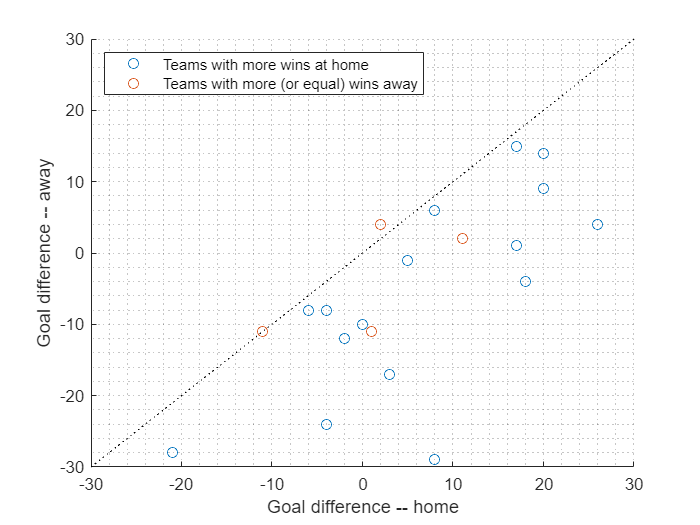

xlabel("Goal difference -- home")
ylabel("Goal difference -- away")
legend("Teams with more wins at home","Teams with more (or equal) wins away", "AutoUpdate", "off", "Location", "northwest")
hold on
plot([-30 30], [-30 30], "k:")
hold off